clc;
close all;

Task 1:

listOfNotes = [440,495,550,660,733,825,0];
Fs = 8e3;
durationOfEachNote= (Fs * 0.5);
resultingTimeDomainSignal = generate_melody(durationOfEachNote,Fs,listOfNotes);

Task 2:

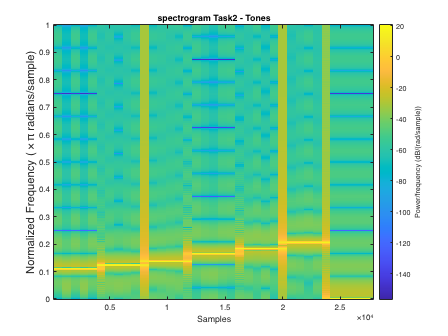

window = 1000;
y = resultingTimeDomainSignal;
spectrogram(y,window,(0.25*window),'yaxis')
title("spectrogram Task2 - Tones")

print -depsc spectrogramTask2

Task 3:

I hear twinkle twinkle little star when i play the audi file.

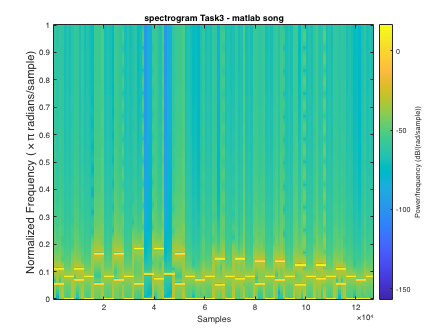

tableTwo = [440,0,440,0,660,0,660,0,733,0,733,0,660,0,0,0,587,0,587,0,550,0,550,0,495,0,495,0,440,0,0,0];
tableThree = [220,330,275,330,220,330,275,330,220,367,293,367,220,330,275,330,206,330,293,330,220,330,275,330,206,330,293,330,220,330,275,330];

Xmelody = generate_melody(durationOfEachNote,Fs,tableTwo);
Xchorus = generate_melody(durationOfEachNote,Fs,tableThree);

xm = 0.6*(Xmelody)+0.4*(Xchorus);

spectrogram(xm,1024,24,'yaxis')
title("spectrogram Task3 - matlab song")
print -depsc spectrogramTask3


fileName1 = "Task3AudioFile.wav";
audiowrite(fileName1,xm,Fs);

[y, Fs] = audioread('Task3AudioFile.wav');
sound(y,Fs);

Task 4:

I hear twinkle twinkle little star but it sounds like some of the chorus notes are attenuated. Teh filter is a high pass filter.

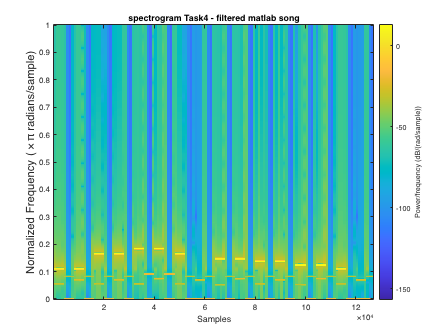

a = [0.62477732,-2.444978,3.64114,-2.444978,0.62477732];
b = [1,-3.1820023,3.9741082,-2.293354,0.52460587];

xf = iir_filter(x,a,b);
spectrogram(xf,1024,24,'yaxis');
title("spectrogram Task4 - filtered matlab song")
print -depsc spectrogramTask4


fileName2 = "Task4AudioFile.wav";
audiowrite(fileName2,xf,Fs);


[b, Fs] = audioread('Task4AudioFile.wav');
sound(b,Fs);

Task 5:

We can see that this is a high pass filter. This allows high frequency components of the song to pass but attenuates lower frequency componants. This directly affects the chorus notes which are all 400Hz and below by making the amplutude smaller, thus making the notes sound weaker.  

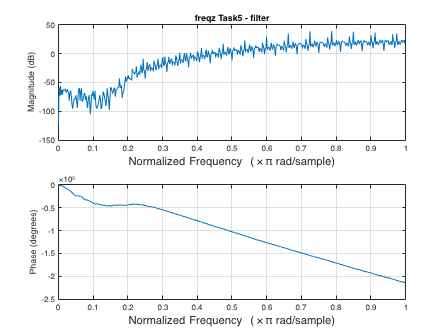

freqz(a,b);
title("freqz Task5 - filter")
print -depsc freqzTask5

Task 6

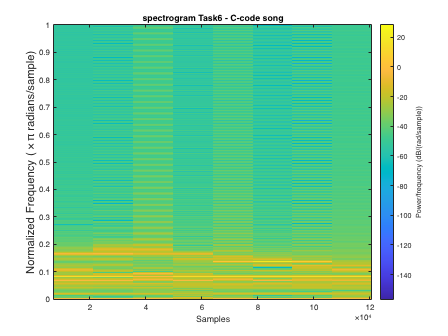

[xc,Fs] = audioread("song.wav");
sound(xc,Fs)
spectrogram(xc,'yaxis')
title("spectrogram Task6 - C-code song")
print -depsc spectrogramTask6

l2 = norm(xm - xc)/norm(xm);
l2

l2 = 3.6201e-05

Task 7

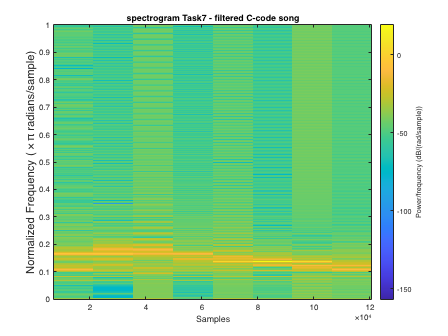

Requested 128000x128000 (122.1GB) array exceeds maximum array size preference (32.0GB). This might cause MATLAB to become unresponsive.

Related documentation

3.6201e-05

function filtered = iir_filter(x,a,b)

    b0 = b(1);
    b1 = b(2);
    b2 = b(3);
    b3 = b(4);
    b4 = b(5);
    a0 = a(1);
    a1 = a(2);
    a2 = a(3);
    a3 = a(4);
    a4 = a(5);
    
    y = [];
    %calc the first 4 terms
    y(1) = (a0*x(1))/b0;
    y(2) = (a0*x(2) + a1*x(2-1) - b1*y(2-1))/b0;
    y(3) = (a0*x(3) + a1*x(3-1) + a2*x(3-2) - b1*y(3-1) - b2*y(3-2))/b0;
    y(4) = (a0*x(4) + a1*x(4-1) + a2*x(4-2) + a3*x(4-3) - b1*y(4-1) - b2*y(4-2) - b3*y(4-3))/b0;
    
    for n = (1+4):(length(x))
        y(n) = (a0*x(n) + a1*x(n-1) + a2*x(n-2) + a3*x(n-3) + a4*x(n-4) - b1*y(n-1) - b2*y(n-2) - b3*y(n-3) - b4*y(n-4)) / b0;
    end
    filtered = y;
end

function newSignal = generate_melody(duration,Fs,ListOfNotes)
    b = [];
    for v = ListOfNotes
        r = generate_sigs(v,Fs,duration);
        r = transpose(r);
        b=[b;r];
    end
    newSignal = b;
end

function x = generate_sigs(f,Fs,L)
    t = 0:1/Fs:L/Fs - 1/Fs ; 
    x = cos(2*pi*f*t); 
end